# Brusshless Motod Complete model with ESC

The hole diagram is depiccted in the following figure.

# 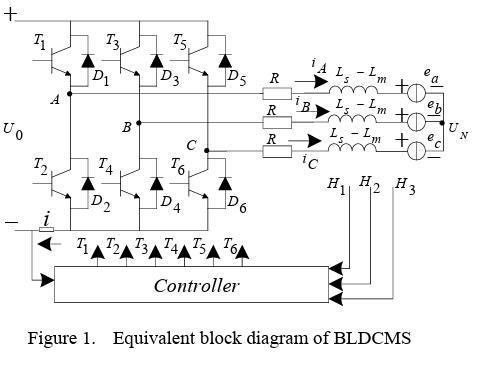

The imput of the controller is a inpulse function

Where T is switch cycle; D is duty cycle and 0 $\leq$D $\leq$ 1, k = 0,1,2...

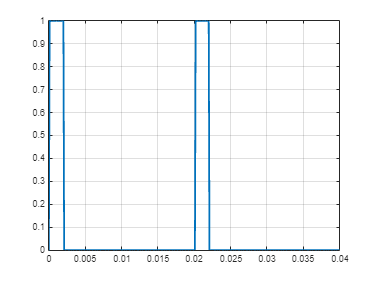

rw.T = 1/50; %%Segun la funcion servo.h de arduino
%rw.D  = 1500*1e-3; %%Dutty Cycle
rw.D  = 2000*1E-6/rw.T; %%Dutty Cycle (1000us -- 0%rpm, 2000us--100%rpm)

time = 0:1E-4:2*rw.T;

pwm = myPW(rw.T,rw.D,time);

figure()    
plot(time,pwm,'LineWidth',2); grid on;

function u = myPW(T,D,t)
u = zeros(1,length(t));
K = 0;
 for i=1:length(t)
    if (t(i) > K*T && t(i) <= (K+D)*T)
        u(i) = 1;
    elseif (t(i) > (K+D)*T && t(i) <= (K+1)*T)
        u(i) = 0;
    end
    if(t(i)>(K+1)*T)
        K = K+1;
    end
 end
end

The hole diagram system for the RW is 

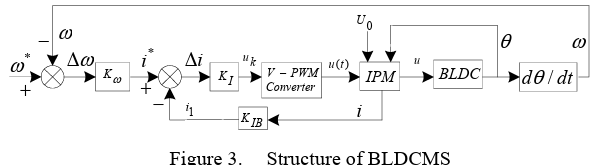

Suppose EMF is 120 flattened trapezoidal waveform  and phase current is 120 rectangular waveform, in a, b, c  coordinate system, a BLDC motor can be represented as 

Where u_a, u_b, u_c are terminal voltages with reference to ground e_a, e_b, e_c are back EMF, i_a, i_b, and i_c are phase current, R is phase resistance,L_s, L_m are self and mutual phase inductance respectively.

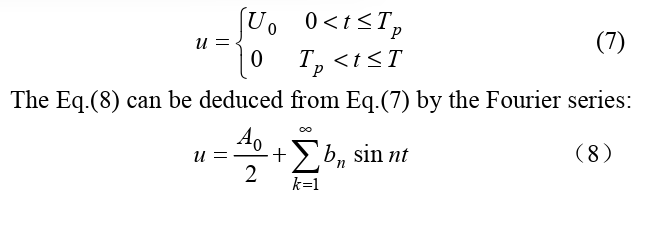

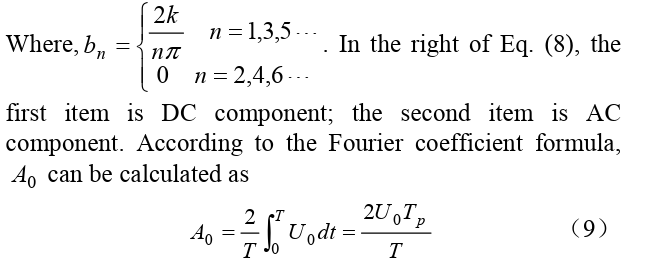

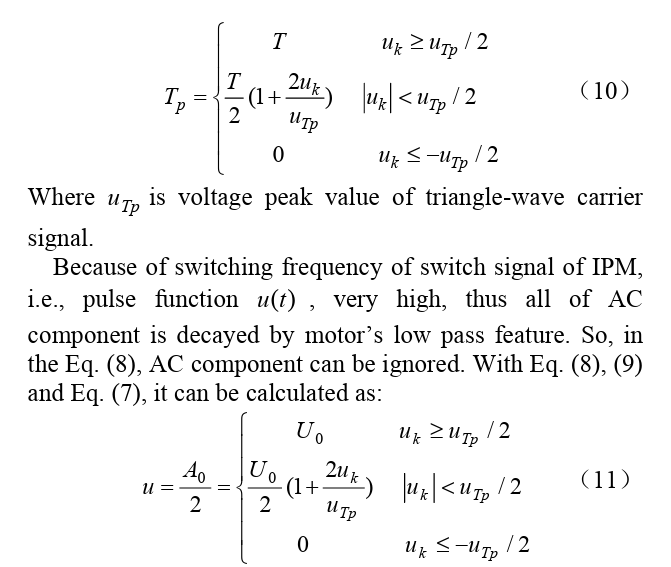

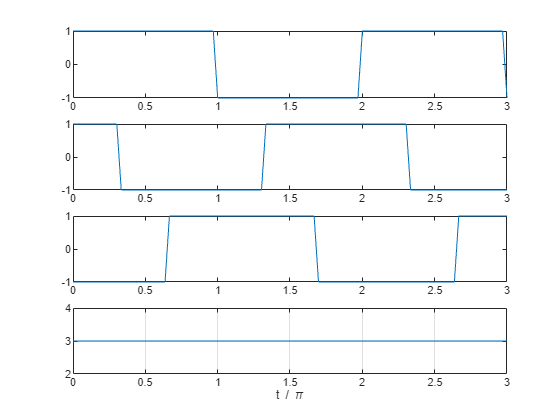

t = linspace(0,3*pi)';
x  = square(t);
x1 = square(t+2*pi/3);
x2 = square(t-2*pi/3);

figure
subplot(4,1,1)
plot(t/pi,x); hold on;
subplot(4,1,2)
plot(t/pi,x1);
subplot(4,1,3)
plot(t/pi,x2);
subplot(4,1,4)
plot(t/pi,(abs(x)+abs(x1)+abs(x2)),'')
xlabel('t / \pi')
grid on

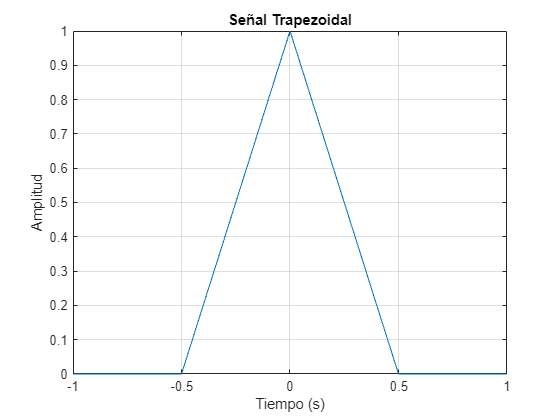

% Parámetros de la señal
T = 1; % Duración de la señal
Ts = 0.01; % Tiempo de muestreo
t = -T:Ts:T; % Vector de tiempo

% Generar la señal trapezoidal
y = tripuls(t, T);

% Graficar la señal
figure;
plot(t, y);
title('Señal Trapezoidal');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

%%%Leer datos de matlab
% Define el nombre del archivo
nombre_archivo = 'RPMdata1.xlsx';

% Lee el archivo Excel
datos = readtable(nombre_archivo);


% Muestra los primeros 5 registros
head(datos)

    Input_PWM_    time_s_    Current_A_    Potencia_W_    CurrentPasos    Velocidad_rpm_
    __________    _______    __________    ___________    ____________    ______________

       1100          1          0.18           2.16          0.591              4495    
       1101          2         0.184          2.208          0.699              4477    
       1102          3         0.182          2.184          0.616              4455    
       1103          4         0.182          2.184          0.642              4437    
       1104          5         0.183          2.196          0.585              4425    
       1105          6         0.182          2.184          0.562            4404.1    
       1106          7         0.182          2.184           0.59              440

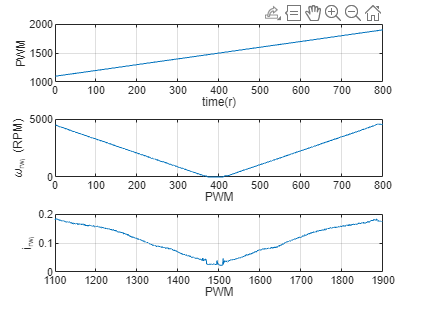


figure()
subplot(3,1,1)
plot(datos.time_s_, datos.Input_PWM_); grid on; 
xlabel('time(s)'); ylabel('PWM');
subplot(3,1,2)
plot(datos.time_s_,datos.Velocidad_rpm_); grid on; 
xlabel('PWM'); ylabel('\omega_{rw_i} (RPM)');
subplot(3,1,3)
plot(datos.Input_PWM_,datos.Current_A_); grid on; 
xlabel('PWM'); ylabel('i_{rw_i}');


function y = squarePulse(t, T)
    % t: tiempo
    % T: periodo del pulso cuadrado
    y = square(2*pi*t/T);
end

%**************************************************************************
% AUTHOR: Brayan Espinoza 3/10/2020
% DESCRIPTION: 
% This program contains the steady-state model for a brushless motor
% developed by José A. Becerra-Vargas in the article "Estimation parameters 
% and black box model of a brushless DC motor".
% IMPORTANT: 
%
% *************************************************************************

function [x_dot,y] = BrushelessModel(t,x,u,const)
%Define inputs
%u:     Vpwm (Vmean)
%kt:    Torque constant (N*m/A)
%ke:    Constante contraelectromotriz (V/(Rad/s))
%kc:    Constante de friccion de Coulomb (N*m*s)
%J:     Rotor inertia (kg*m^2)
%B:     Constante de friccion viscosa (N*m*s)
%L:     Inductancia (H)
%R:     Resistencia (R)
%Tcte:  Torque de la carga

w  =x(1);   %Reaction wheel angular rate
i  =x(2);   %Reaction wheel current face
%%%ReadConstants
kt =const(1);
J  =const(2);
B  =const(3);
Kc =const(4);
L  =const(5);
R  =const(6);
Ke =const(7);
d  =const(8);
ws  =const(8);

%Perform ecuations
w_dot=1/J*(kt*i-B*w-sign(w)*(Kc+d*exp(w^2/ws)));
i_dot=1/L*(u-R*i-Ke*w);

%x_dot vector
x_dot=[w_dot,i_dot]';

%Output equation (Angular rate)
y=[x(1);x(2)];

end